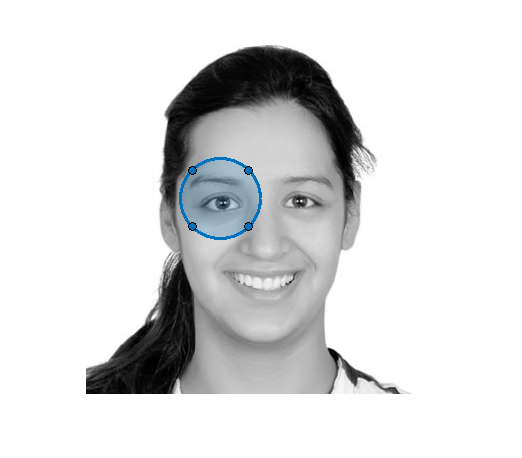

clear;
originalImage1 = imread("https://i.ibb.co/fC8Ptny/eye.jpg");
originalImage1 = rgb2gray(originalImage1);

originalImage2 = imread("https://i.ibb.co/R38pnz5/Hand.jpg");
originalImage2 = rgb2gray(originalImage2);

% resizing images to the same size
[rows1, cols1] = size(originalImage1);
[rows2, cols2] = size(originalImage2);
rows = min(rows1,rows2);
cols = min(cols1,cols2);
originalImage1 = imresize(originalImage1,[rows cols]);
originalImage2 = imresize(originalImage2,[rows cols]);

% create binary mask 
figure; imshow(originalImage1);
region = drawcircle('Center',[135,170],'Radius',40);

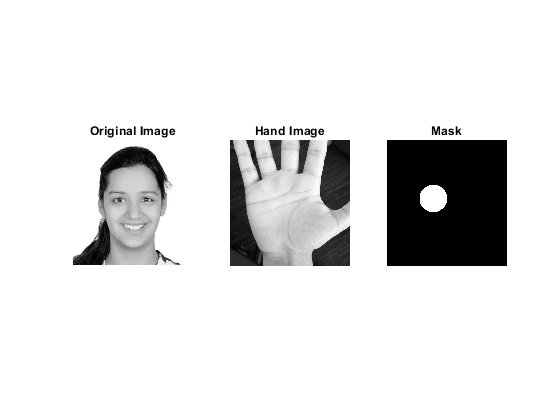

mask = createMask(region);

% displaying original images 
plotImagesInSubplot(originalImage1,'Original Image', originalImage2,'Hand Image', mask,'Mask')


% filter for downsampling
binomialFilter = [1/16 4/16 6/16 4/16 1/16];

% Gaussian Pyramid for image 1
pyramid1Step1 = originalImage1;
pyramid1Step2 = GaussianPyramid(pyramid1Step1,binomialFilter);
pyramid1Step3 = GaussianPyramid(pyramid1Step2,binomialFilter);
disp("Gaussian Pyramid for face image :")

Gaussian Pyramid for face image :


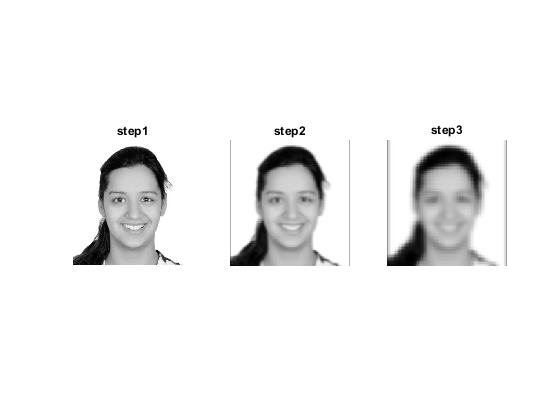

plotImagesInSubplot(pyramid1Step1,'step1',pyramid1Step2,'step2',pyramid1Step3,'step3');

% Laplacian pyramid for image 1
lapPStep1 = LaplacianPyramid(pyramid1Step1,pyramid1Step2);
lapPStep2 = LaplacianPyramid(pyramid1Step2,pyramid1Step3);
lapPStep3 = pyramid1Step3;
disp("Laplacian Pyramid for face image :")

Laplacian Pyramid for face image :


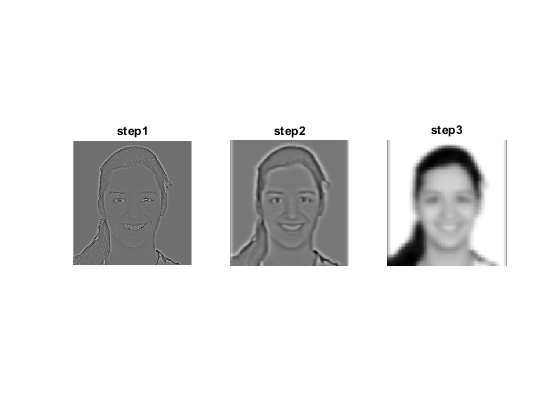

plotImagesInSubplot(lapPStep1,'step1',lapPStep2,'step2',lapPStep3, 'step3');



% Gaussian Pyramid for image 2
pyramid2Step1 = originalImage2;
pyramid2Step2 = GaussianPyramid(pyramid2Step1,binomialFilter);
pyramid2Step3 = GaussianPyramid(pyramid2Step2,binomialFilter);
disp("Gaussian Pyramid for hand image :")

Gaussian Pyramid for hand image :


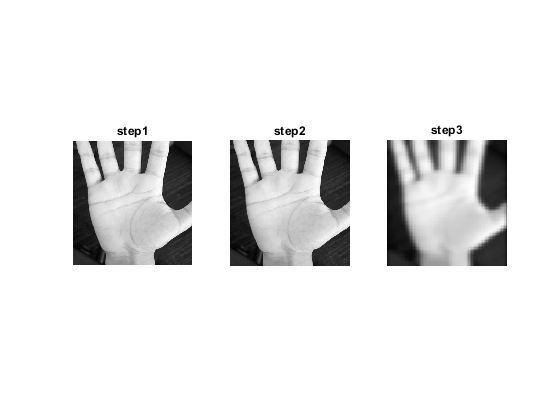

plotImagesInSubplot(pyramid2Step1,'step1',pyramid2Step1,'step2',pyramid2Step3,'step3');

% Laplacian pyramid for image 2
lapP2Step1 = LaplacianPyramid(pyramid2Step1,pyramid2Step2);
lapP2Step2 = LaplacianPyramid(pyramid2Step2,pyramid2Step3);
lapP2Step3 = pyramid2Step3;
disp("Laplacian Pyramid for hand image :")

Laplacian Pyramid for hand image :


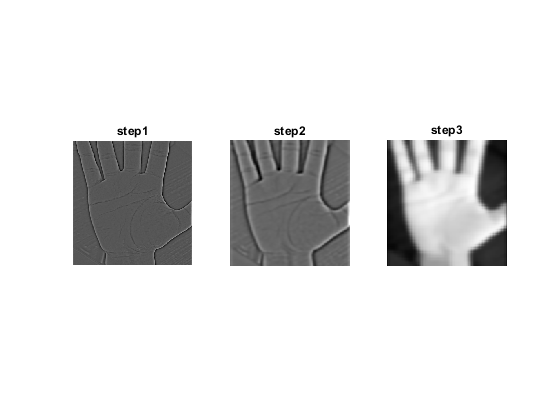

plotImagesInSubplot(lapP2Step1,'step1',lapP2Step2,'step2',lapP2Step3,'step3');

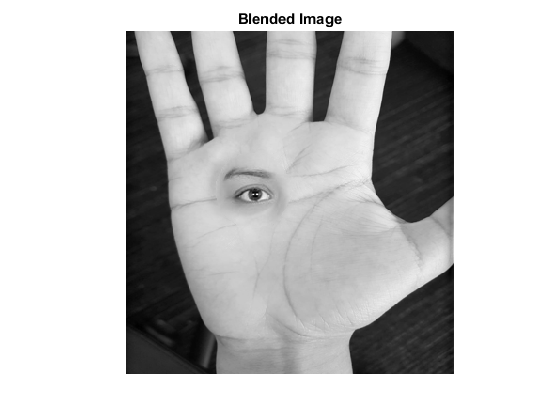


% create gaussian pyramid for the mask
mask = double(mask);
gMaskStep1 = mask;
gmaskStep2 = GaussianPyramid(gMaskStep1,binomialFilter);
gmaskStep3 = GaussianPyramid(gmaskStep2,binomialFilter);

% multiply the laplacian pyramids with the gausian mask 
% for first image 
m1Step1 = GauLapWithMask(gMaskStep1, lapPStep1);
m1Step2 = GauLapWithMask(gmaskStep2, lapPStep2);
m1Step3 = GauLapWithMask(gmaskStep3, lapPStep3);

% create gaussian pyramid for inverse mask
maskinv = double(1 - mask);

gmaskinvStep1 = maskinv;
gmaskinvStep2 = GaussianPyramid(gmaskinvStep1, binomialFilter);
gmaskinvStep3 = GaussianPyramid(gmaskinvStep2, binomialFilter);
% multiply the laplacian pyramid with the gaussian mask inv
% for second image 

m2Step1 = GauLapWithMask(gmaskinvStep1,lapP2Step1);
m2Step2 = GauLapWithMask(gmaskinvStep2, lapP2Step2);
m2Step3 = GauLapWithMask(gmaskinvStep3, lapP2Step3);

% calculating the final step 
finalStep1 = add(m1Step1,m2Step1);
finalStep2 = add(m1Step2,m2Step2);
finalStep3 = add(m1Step3,m2Step3);
%plotImagesInSubplot(finalStep1,finalStep2,finalStep3);

% colapsing laplacian to get the image 
a = Expand(finalStep3);
[rf1, cf1, ~] = size(finalStep2);
b = a(1:rf1, 1:cf1) + finalStep2;
c = Expand(b);
[rf2, cf2, ~] = size(finalStep1);
d = c(1:rf2, 1:cf2) + finalStep1;
figure;
imshow((d),[],'InitialMagnification','fit'),title('Blended Image');

function final = add(f1, f2)
    final = f1 + f2;
return;
end

function multiplyStep = GauLapWithMask (m, p)
    [r1,c1] = size(m);    
    p = p(1:r1, 1:c1);
    multiplyStep = m .* p;  
return;
end

function lap = LaplacianPyramid(gpMain, gpReduced)    
    increaseImage = Expand(gpReduced);
    [r,c] = size(gpMain);    
    increaseImage = increaseImage(1:r, 1:c);
    lap = double(gpMain) - double(increaseImage);
    return;
end

function expandedImage = Expand(gpreduced)
    bilinearfilter = [1/4 2/4 1/4; 2/4 4/4 2/4; 1/4 2/4 1/4];
    [rows, cols, ~] = size(gpreduced);
    eImage  = zeros(2*rows, 2*cols);
    eImage(1:2:end, 1:2:end) = gpreduced;
    expandedImage = conv2(eImage,bilinearfilter,"same");    
end

function reducedImage = GaussianPyramid (imageToReduce,binomialFilter)
    imageblur1 = imgaussfilt(imageToReduce,2.5);
    reducedImage = convn(imageblur1(1:2:end, 1:2:end),binomialFilter, 'same');
return; 
end

function plotImagesInSubplot (img1,title1,img2,title2,img3,title3)
    figure;
    subplot(1,3,1),imshow((img1),[],'InitialMagnification','fit'),title(title1);
    subplot(1,3,2),imshow((img2),[],'InitialMagnification','fit'),title(title2);
    subplot(1,3,3),imshow((img3),[],'InitialMagnification','fit'),title(title3);
end

